# Estimate drainage time for southern highlands aquifer

clc, clear
set_demo_defaults
yr2s = 60^2*24*365.25; % seconds per year
R_mars = 3389508; % [m] Mars' mean radius 
g_mars = 3.711;   % [m/s^2] grav. acceleration on Mars
rho = 1e3;      % [kg/m^3] desity of water 
mu = 1e-3;      % [Pa s] water viscosity

Use numerical solution to estimte a drainage time for the southern highlands aquifer

### Guess-timate the physical properties

#### Fit porosity exponent, m

Here we fit the exponent for the porosity power-law, $\phi(z) = \phi_0 z^m$, to the exponential solution, $\phi(d) = \phi_s\mathrm{e}^{-d/d_0}$, used by Clifford and Parker (2001). Here $d$ is the depth beneath the surface and $z = d_\mathrm{max}-d$, where $d_\mathrm{max}$ is the maximum depth of the aquifer. Hence our model assumed thate $\phi$ becomes zero as $d_\mathrm{max}$, unlike the exponential model. As such the power-law model has three free parameters the coefficient $\phi_0$, the exponet $m$ and finite aquifer depth $d_\mathrm{max}$. We choose $d_\mathrm{\max}$ adetermine the remaining paramters by matching the porosity of the exponetial model at $d=0$ and $d=d_\mathrm{max}/2$ and obtain

$m=\frac{d_\mathrm{max}}{2 d_0 \log(2)}$ and $\phi_0 = \frac{\phi_s}{d_\mathrm{max}^m}$.

The exonent $m$ is independent of the surface porosity $\phi_s$, so that we cavary $\phi_s$ without changing $m$. For and aquifer of $d_\mathrm{max}=10$ km a fitting the porosity at a depth of $d_\mathrm{max}/2$ we obtain $m\approx 2.5$. The resulting curves for the porosity are shown the figure. Perhaps a better choice would be to fit $\phi_0$ and $m$ to match $\phi_s$ and the total pore volume.

dmax = 10e3; % [km] max. aquifer depth
d0 = 2.8375e3;  % decay depth

phi_clifford = @(d,phi_s,d0) phi_s*exp(-d/d0);
phi_s_min = 0.3;
phi_s_max = 0.5;


m_best = dmax/(2*d0*log(2))

m_best = 2.5422

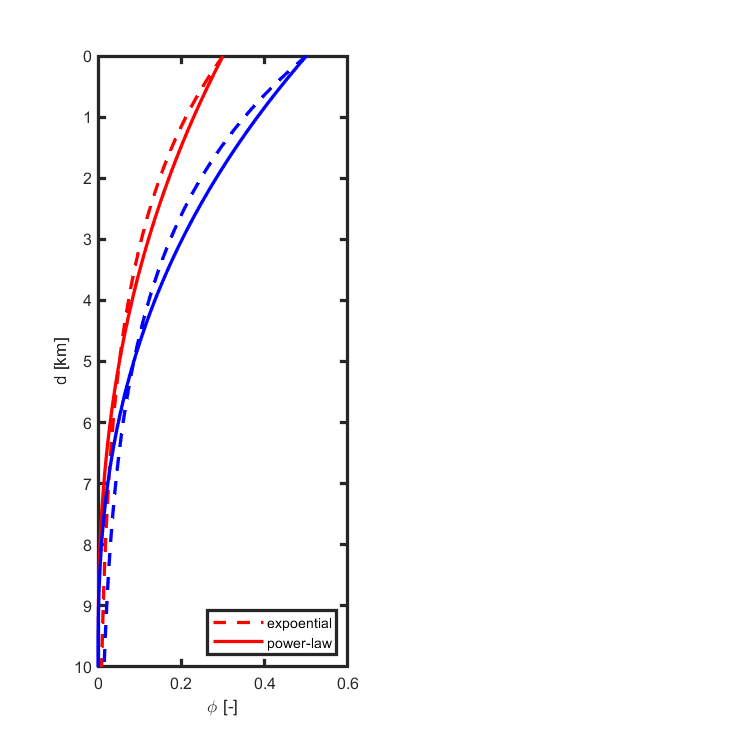

phi0_best = @(phi_s,m) phi_s/(dmax^m);  

phi = @(z,phi0,m_exp) phi0*z.^m_exp;

d = linspace(0,10e3,1e2)';
z = dmax-d;
figure('position',[10 10 600 600])
subplot 121
plot(phi_clifford(d,phi_s_min,d0),d/1e3,'r--'), hold on
plot(phi(z,phi0_best(phi_s_min,m_best),m_best),d/1e3,'r-')
plot(phi_clifford(d,phi_s_max,d0),d/1e3,'b--')
plot(phi(z,phi0_best(phi_s_max,m_best),m_best),d/1e3,'b-')
set(gca,'ydir','reverse')
xlabel '\phi [-]', ylabel 'd [km]'
legend('expoential','power-law','location','southeast')

#### Fit the hydraulic conductivity exponent, n

The power-law for the permeability decay with depth is fit to the Manning and Ingebrisen (1999), which is a power-law decay with depth. As such we simply have


$$k_0 = \frac{k_0^\mathrm{IM}}{(d_\mathrm{max}-10^3)^n}$$


where $k_0^\mathrm{IM}$ is the reference permeability of Manning and  Ingebritsen at 1 km depth.

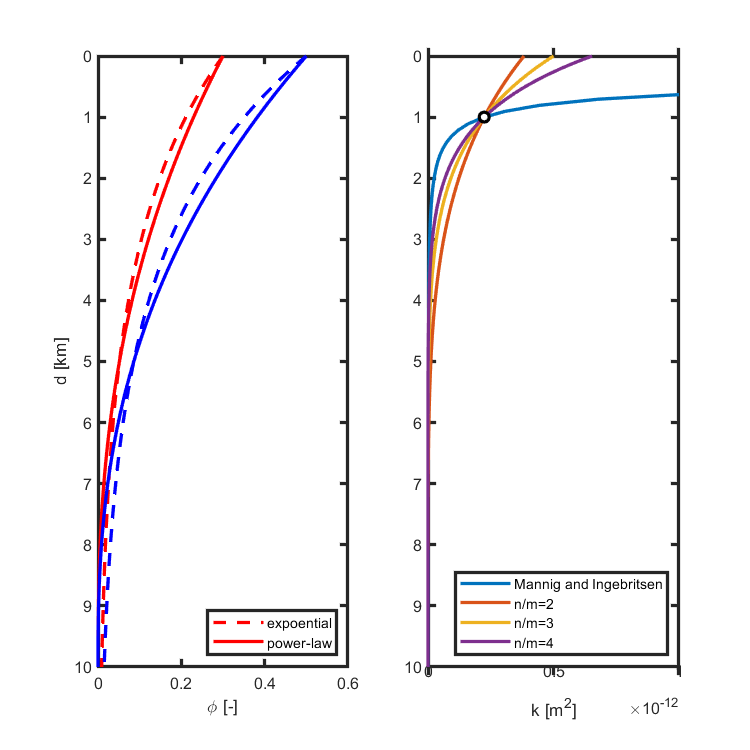

k0_MI = 10^(-12.65); % [m^2] ref. permeability at 1km depth Manning and Ingebritsen (1999)
alpha = 3.2;
k_MI = @(d) k0_MI*d.^(-alpha);

k0 = @(n) k0_MI/(dmax-1e3)^n;
k = @(z,n) k0(n)*z.^n;

subplot 122
plot(k_MI(d/1e3),d/1e3), hold on
plot(k(z,2*m_best),d/1e3)
plot(k(z,3*m_best),d/1e3)
plot(k(z,4*m_best),d/1e3)
plot(k0_MI,1,'ko','markerfacecolor','w','markersize',6)
set(gca,'ydir','reverse')
xlabel 'k [m^2]', 
xlim([0 1e-12])
legend('Mannig and Ingebritsen','n/m=2','n/m=3','n/m=4','location','southeast')

The resulting exponent for the permeability decline is rather large

m_best*2

ans = 5.0844

m_best*4

ans = 10.1688

Based on the permeabilith we can define the hydraulic conductivity 


$$K_0 = \frac{k_0\rho g}{\mu}$$
 

and hydraulic diffusivity


$$D_h = \frac{K_0 (m+1)}{\phi_0(n+1)}$$


K0 = @(n) k0(n)*rho*g_mars/mu;
D_hyd = @(phi_s,m,n) K0(n)*(m+1)/(phi0_best(phi_s,m)*(n+1));

## Estimating drainage timescale for the Martial highlands

theta_bnd = pi-acos(1/3);   % [rad] co-lattitude of the dichotomy boundary
h0 = dmax;                  % [m] initial height of the water table 

To estimate the drainage timescale for the Martial highlands we have the following equations of the spherical shell

PDE: $\phi_0 h^m \frac{\partial h}{\partial t} -\frac{1}{R\sin \theta} \frac{\mathrm{d}}{\mathrm{d}\theta}\left[\sin\theta \frac{K_0}{n+1}\frac{h^{n+1}}{R}\frac{\mathrm{d}h}{\mathrm{d}\theta}\right] = 0$ on $\theta \in \left[0,\,\theta_b\right]$

BC's: $\left.\frac{\mathrm{d}h}{\mathrm{d}\theta}\right|_0 = 0$ and $h(\theta_b)=0$

IC: $h(\theta,0) = h_0$

#### Parameter ranges

Using the fits above the values of $\phi_0$ and $K_0$ in the governing equation, take extreme values

phi0_min = phi0_best(0.3,m_best)

phi0_min = 2.0340e-11

phi0_max = phi0_best(0.5,m_best)

phi0_max = 3.3900e-11

the values for $K_0$ are even more extreme

K0_max = K0(2*m_best)

K0_max = 6.5251e-27

K0_min = K0(4*m_best)

K0_min = 5.1249e-47

and the resulting hydraulic diffusivity is very pooly scaled and can range over more than 10 orders of magnitude

D_hyd_max=D_hyd(0.3,m_best,2*m_best)

D_hyd_max = 1.8677e-16

D_hyd_min=D_hyd(0.5,m_best,4*m_best)

D_hyd_min = 4.7947e-37

### Dimensionless governing equation

As such it is useful to non-dimensionalize the governing equation to improve the scaling. Here we introduce the scales

$h' = \frac{h}{h_0}$,  and $t' = \frac{t}{t_c}$ where we choose the characteristic time $t_c = \frac{\phi_0 R^2(n+1)}{K_0h_0^{n-m+1}}$ and have the dimensionless governing equations

PDE: ${h'}^m \frac{\partial h'}{\partial t} -\frac{1}{\sin \theta} \frac{\mathrm{d}}{\mathrm{d}\theta}\left[\sin\theta {h'}^{n+1}\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right] = 0$ on $\theta \in \left[0,\,\theta_b\right]$

BC's: $\left.\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right|_0 = 0$ and $h'(\theta_b)=0$

IC: $h'(\theta,0) = 1$

The characteristic timescale, $t_c$, indicates the time it takes for the change in head to propagate from the dichotomy to the south pole.  This *propagation timescale* appears to be 40 to 80 million years. The *drainage timescale* is orders-of magnitude longer than this propagation timescale. It is currently unclear (to me) how to properly define the drainage timescale. 

tc = @(phi_s,m,n_mult)  phi0_best(phi_s,m)*R_mars^2*(n_mult*m+1)/(K0(n_mult*m)*h0^(n_mult*m-m+1));

tc_min = tc(0.3,m_best,2)/yr2s

tc_min = 4.6813e+07

tc_max = tc(0.5,m_best,4)/yr2s

tc_max = 8.3822e+07

### Numerical solution

Here we use the values estimated above to compute the timescale for the drainage of the Martian highland aquifer. These are fresh of the press estimates that should be taken with a grain of salt, but it appears that the time to drain 90% of the water is on the order of the age of the solar system! Taken a face value, this would imply that the deep Martian hydrosphere is still adjusting to changes in Mars climate 3 billion years ago. Taking this yet another step further, this means that deep Martian groundwater may have persisted over its entire life time, providing a prodected deep habitat. Of course, this is a good place to remember that we have made many simplifying assumptions :-).

It is encouraging though that the decline follows a power-law and the exponent seems to be predicted by the linear thery of Zheng et al. (2013)! This suggests that the solution on the spherical shell is still self-similar and the theory can be extented. Theoretical results would allow to bracket the decay rates for large range of possible decay rates of porosity and permeability.

n_mult = 3;
m_exp = m_best;
n_exp = n_mult*m_exp;


## Analytical solution

fprintf('Analytical solution:\n')

Analytical solution:


% make grid so that last cell center is exactly 1;
%Nx = 200;
%dx = 1/(Nx-.5);
%xmax = Nx*dx;
kmax= 50;

Grid.xmin = 0; Grid.xmax = 1.0; Grid.Nx = 200;
Grid.geom = 'spherical_shell', Grid.R_shell = 1;

Grid = struct with fields:
    xmin: 0
    xmax: 1
      Nx: 200
    geom: 'spherical_shell'



%Grid.xmin = 0; Grid.xmax = xmax; Grid.Nx = Nx;
%Grid.geom = 'spherical_shell'; Grid.R_shell = 1;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);

Operators built for 1D spherical shell geometry (R = 1.00e+00)n.

fs = zeros(Grid.Nx,1);   % r.h.s
M = Grid.dx/2*abs(G);   % mean operator

%% Residual
F1  = @(u,n) spdiags(M*u.^(n+1),0,Grid.Nx+1,Grid.Nx+1);
f2  = @(u,n,m) (m+1)/(n-m+1)*u.^(m+1);
res = @(u,n,m) D*(F1(u,n)*G*u)+f2(u,n,m);

%% Boundary conditions - for update!
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = 0;
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,I] = build_bnd(BC,Grid,I);

%% Load stepping
Nload = 18;
Niter = 20;
m_vec = linspace(0,m_best,Nload);
n_vec = 3*m_vec;

% initial guess
u = 1-Grid.xc;
U = zeros(Grid.Nx,Nload);
Int = zeros(Nload,1);
for i=1:Nload
    fprintf('Solving for m = %3.1f and n=%3.1f:\n',m_vec(i),n_vec(i))
    u = solve_self_similar_ode(res,u,n_vec(i),m_vec(i),B,N,BC,kmax);
    U(:,i) = u;
    fprintf('\n\n')
    Int(i) = sum(u.^(m_vec(i)+1).*sin(Grid.xc)*Grid.dx);
end

Solving for m = 0.0 and n=0.0:


it = 1: nres = 2.11e+02  ndu = 2.68e+00
it = 2: nres = 4.87e+01  ndu = 9.48e-01
it = 3: nres = 9.46e+00  ndu = 1.66e-01
it = 4: nres = 8.64e-01  ndu = 1.12e-02
it = 5: nres = 6.76e-03  ndu = 5.21e-04
it = 6: nres = 3.43e-07  ndu = 2.48e-06
it = 7: nres = 1.60e-11  ndu = 1.05e-10


Solving for m = 0.1 and n=0.4:


it = 1: nres = 1.95e+01  ndu = 3.06e+00
it = 2: nres = 4.67e+00  ndu = 1.12e+00
it = 3: nres = 6.23e-01  ndu = 2.51e-01
it = 4: nres = 1.20e-02  ndu = 1.37e-02
it = 5: nres = 3.02e-06  ndu = 5.16e-05
it = 6: nres = 3.79e-11  ndu = 3.72e-09


Solving for m = 0.3 and n=0.9:


it = 1: nres = 1.02e+01  ndu = 2.05e+00
it = 2: nres = 2.18e+00  ndu = 6.07e-01
it = 3: nres = 1.65e-01  ndu = 8.18e-02
it = 4: nres = 7.45e-04  ndu = 1.70e-03
it = 5: nres = 1.62e-08  ndu = 1.89e-06
it = 6: nres = 1.79e-11  ndu = 2.92e-11


Solving for m = 0.4 and n=1.3:


it = 1: nres = 7.15e+00  ndu = 1.49e+00
it = 2: nres = 1.34e+00  ndu = 3.68e-01
it = 3: nres = 6.07e-02  ndu = 3.28e-02
it = 4: nres = 8.93e-05  ndu = 3.65e-04
it = 5: nres = 7.64e-10  ndu = 1.85e-07


Solving for m = 0.6 and n=1.8:


it = 1: nres = 5.50e+00  ndu = 1.13e+00
it = 2: nres = 8.87e-01  ndu = 2.38e-01
it = 3: nres = 2.54e-02  ndu = 1.52e-02
it = 4: nres = 1.42e-05  ndu = 1.10e-04
it = 5: nres = 9.78e-11  ndu = 2.62e-08


Solving for m = 0.7 and n=2.2:


it = 1: nres = 4.43e+00  ndu = 8.84e-01
it = 2: nres = 6.14e-01  ndu = 1.61e-01
it = 3: nres = 1.15e-02  ndu = 7.81e-03
it = 4: nres = 2.69e-06  ndu = 4.03e-05
it = 5: nres = 3.59e-11  ndu = 4.71e-09


Solving for m = 0.9 and n=2.7:


it = 1: nres = 3.68e+00  ndu = 7.05e-01
it = 2: nres = 4.38e-01  ndu = 1.13e-01
it = 3: nres = 5.54e-03  ndu = 4.36e-03
it = 4: nres = 5.93e-07  ndu = 1.67e-05
it = 5: nres = 3.13e-11  ndu = 1.03e-09


Solving for m = 1.0 and n=3.1:


it = 1: nres = 3.13e+00  ndu = 5.72e-01
it = 2: nres = 3.22e-01  ndu = 8.15e-02
it = 3: nres = 2.82e-03  ndu = 2.59e-03
it = 4: nres = 1.50e-07  ndu = 7.52e-06
it = 5: nres = 3.92e-11  ndu = 2.69e-10


Solving for m = 1.2 and n=3.6:


it = 1: nres = 2.71e+00  ndu = 4.71e-01
it = 2: nres = 2.41e-01  ndu = 6.04e-02
it = 3: nres = 1.51e-03  ndu = 1.62e-03
it = 4: nres = 4.38e-08  ndu = 3.63e-06
it = 5: nres = 4.62e-11  ndu = 8.55e-11


Solving for m = 1.3 and n=4.0:


it = 1: nres = 2.39e+00  ndu = 3.93e-01
it = 2: nres = 1.85e-01  ndu = 4.57e-02
it = 3: nres = 8.40e-04  ndu = 1.06e-03
it = 4: nres = 1.47e-08  ndu = 1.85e-06
it = 5: nres = 4.97e-11  ndu = 3.26e-11


Solving for m = 1.5 and n=4.5:


it = 1: nres = 2.12e+00  ndu = 3.31e-01
it = 2: nres = 1.44e-01  ndu = 3.53e-02
it = 3: nres = 4.86e-04  ndu = 7.17e-04
it = 4: nres = 5.75e-09  ndu = 9.89e-07


Solving for m = 1.6 and n=4.9:


it = 1: nres = 1.90e+00  ndu = 2.82e-01
it = 2: nres = 1.14e-01  ndu = 2.77e-02
it = 3: nres = 2.91e-04  ndu = 5.00e-04
it = 4: nres = 2.60e-09  ndu = 5.50e-07


Solving for m = 1.8 and n=5.4:


it = 1: nres = 1.72e+00  ndu = 2.42e-01
it = 2: nres = 9.15e-02  ndu = 2.20e-02
it = 3: nres = 1.79e-04  ndu = 3.57e-04
it = 4: nres = 1.33e-09  ndu = 3.17e-07


Solving for m = 1.9 and n=5.8:


it = 1: nres = 1.57e+00  ndu = 2.09e-01
it = 2: nres = 7.43e-02  ndu = 1.78e-02
it = 3: nres = 1.13e-04  ndu = 2.61e-04
it = 4: nres = 7.57e-10  ndu = 1.89e-07


Solving for m = 2.1 and n=6.3:


it = 1: nres = 1.44e+00  ndu = 1.82e-01
it = 2: nres = 6.10e-02  ndu = 1.45e-02
it = 3: nres = 7.34e-05  ndu = 1.94e-04
it = 4: nres = 4.64e-10  ndu = 1.15e-07


Solving for m = 2.2 and n=6.7:


it = 1: nres = 1.33e+00  ndu = 1.59e-01
it = 2: nres = 5.06e-02  ndu = 1.20e-02
it = 3: nres = 4.86e-05  ndu = 1.47e-04
it = 4: nres = 3.08e-10  ndu = 7.24e-08


Solving for m = 2.4 and n=7.2:


it = 1: nres = 1.23e+00  ndu = 1.40e-01
it = 2: nres = 4.23e-02  ndu = 9.96e-03
it = 3: nres = 3.28e-05  ndu = 1.13e-04
it = 4: nres = 2.24e-10  ndu = 4.64e-08


Solving for m = 2.5 and n=7.6:


it = 1: nres = 1.14e+00  ndu = 1.24e-01
it = 2: nres = 3.57e-02  ndu = 8.37e-03
it = 3: nres = 2.26e-05  ndu = 8.78e-05
it = 4: nres = 1.75e-10  ndu = 3.04e-08


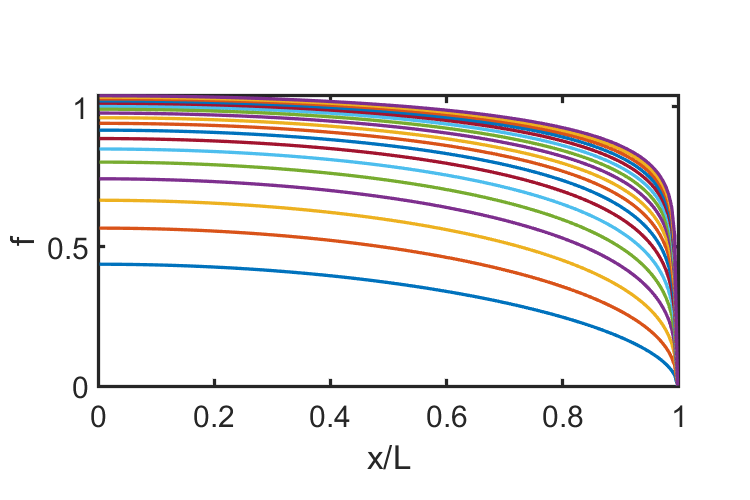

% plot solutions
figure('position',[10 10 600 400])
for i=1:Nload
    plot_self_similar_soln(Grid,U(:,i),n_vec(i),m_vec(i)), hold on
end

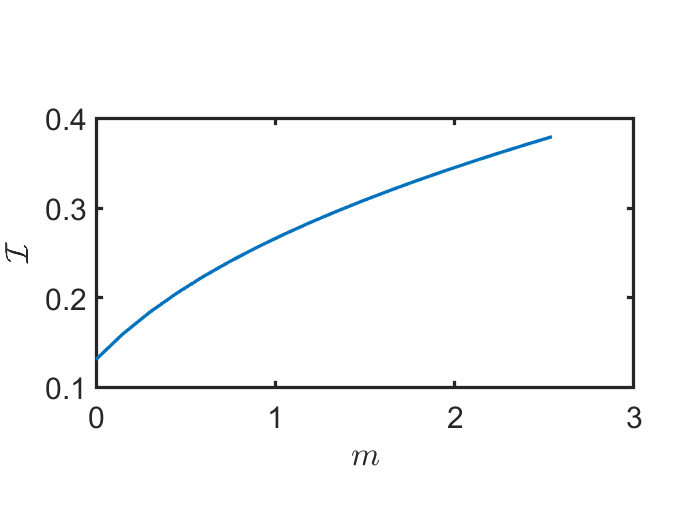

%legend('m=0.0','m=0.5','m=1.0','m=1.5','m=2.0','m=2.5422','location','southwest')

plot_Integralvsm(m_vec,Int)

## Numerical solution

%% Grid and ops
Grid.xmin = 0; Grid.xmax = 1.0; Grid.Nx = 200;
Grid.geom = 'spherical_shell'; Grid.R_shell = 1;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);

Operators built for 1D spherical shell geometry (R = 1.00e+00)n.

M = Grid.dx/2*abs(G);   % mean operator
fs = zeros(Grid.Nx,1);
% Timestepping
tmax = 5e3;
Nt = 2*tmax;
dt = tmax/Nt;

%% Jacobian for transient solution
% Function in accumulation term
s  = @(u) u.^m_exp;
ds = @(u) m_exp*u.^(m_exp-1);
S  = @(u) spdiags(s(u),0,Grid.Nx,Grid.Nx);
dS = @(u) spdiags(ds(u),0,Grid.Nx,Grid.Nx);

% Function in flux term
f  = @(u) u.^(n_exp+1)/(n_exp+1);
df = @(u) u.^n_exp;

F  = @(u) spdiags(M*f(u),0,Grid.Nx+1,Grid.Nx+1);
dF = @(u) spdiags(df(u),0,Grid.Nx,Grid.Nx);

% Other 'function matrices'
U  = @(u,uold) spdiags(u-uold,0,Grid.Nx,Grid.Nx);
GU = @(u)      spdiags(G*u,0,Grid.Nx+1,Grid.Nx+1);

% Residual and Jacobian
res = @(u,uold) S(u)*(u-uold) - dt*D*(F(u)*G*u) - dt*fs;
Jac = @(u,uold) dS(u)*U(u,uold) + S(u) - dt*D*(GU(u)*M*dF(u) + F(u)*G);

%% BC's
BC.dof_dir   = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g         = 0;

BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
[B,N,fn] = build_bnd(BC,Grid,I);

%% Initial condition
hD = ones(Grid.Nx,1);
hD(Grid.dof_xmax) = 0;
M = zeros(Nt+1,1); M(1) = sum(hD*Grid.dx);

%% Time integration
kmax = 10; 
tol = 1e-6;

fprintf('Computing transient solution:\n')

Computing transient solution:


for n = 1:Nt
    hDold = hD;
    nres = norm(res(hD,hDold)); ndhD = 1; k = 0;
    while (nres > tol || ndhD > tol) && k < kmax
        dhD = solve_lbvp(Jac(hD,hDold),-res(hD,hDold),B,BC.g,N);
        hD = hD + dhD;
        nres = norm(N'*res(hD,hDold)); ndhD = norm(N'*dhD);
        k = k+1;
%         fprintf('it = %d: nres = %3.2e  ndhD = %3.2e\n',k,nres,ndhD)
        if k == 1; ndhD = 0; end % to allow exit on first iteration
    end
    if k <= kmax; 
%         fprintf('Newton converged after %d iterations\n\n',k)
    else
        error('Newton did not converged after %d iterations\n\n',k)
    end
    tD = n*dt;
    M(n) = sum(hD.^(m_exp+1)/(m_exp+1).*sin(Grid.xc)*Grid.dx);
end
fprintf('Transient solution computed successfully:\n')

Transient solution computed successfully:


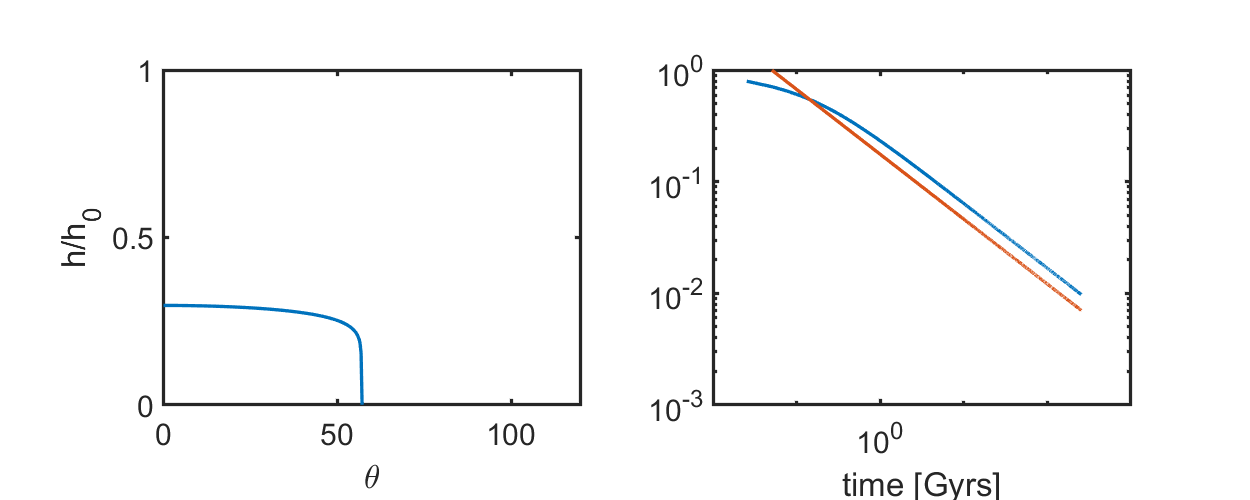


tc_here = tc(0.3,m_exp,n_mult);
M0 = sum(ones(Grid.Nx,1).^(m_exp+1)/(m_exp+1).*sin(Grid.xc)*Grid.dx);
M_theory = @(t) (1./t).^((m_exp+1)/(n_exp-m_exp+1));

figure('position',[10 10 1000 400])
subplot 121
plot(rad2deg(Grid.xc),hD,'-'),
xlabel '\theta', ylabel 'h/h_0'
xlim([0 120])
ylim([0 1])
pbaspect([1 .8 1])

subplot 122
time_vec = [1:Nt+1]*dt;
loglog(time_vec*tc_here/yr2s/1e9,M/M0), hold on
loglog(time_vec*tc_here/yr2s/1e9,M_theory(time_vec))
pbaspect([1 .8 1])
xlim([1e-2,1e3])
ylim([1e-3 1e0])
% legend('numerical','theory')
xlabel 'time [Gyrs]'

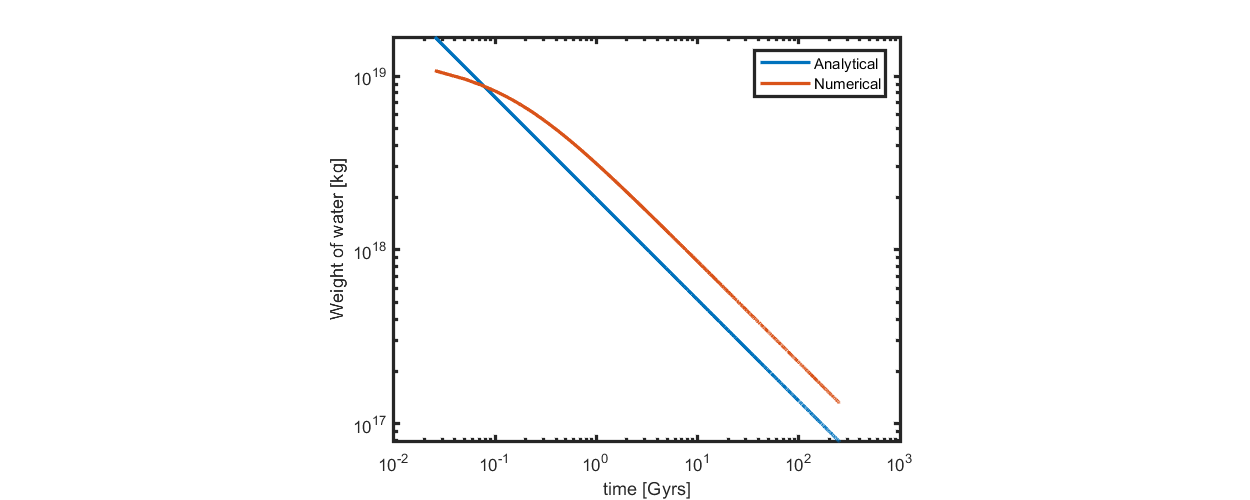


figure('position',[10 10 1000 400])
time_vec = [1:Nt+1]*dt;
Int = 0.382624247672692;
phi_s=0.3;
h_c = (R_mars^2 /(D_hyd(phi_s,m_exp,n_exp)* tc(phi_s,m_exp,3)))^(1/(n_exp-m_exp+1));

W_analytical = 2/(m_exp+1)*rho*phi0_best(phi_s,m_exp)*pi*R_mars^2*(R_mars^2/D_hyd(phi_s,m_exp,n_exp))^((m_exp+1)/(n_exp-m_exp+1))*Int.*M_theory(time_vec*tc_here);
W_numerical  = 2/(m_exp+1)*rho*phi0_best(phi_s,m_exp)*pi*R_mars^2*(R_mars^2/D_hyd(phi_s,m_exp,n_exp))^((m_exp+1)/(n_exp-m_exp+1)).*(M.*(m_exp+1))./tc_here^((m_exp+1)/(n_exp-m_exp+1));
%W_numerical  = 2/(m_exp+1)*rho*phi0_best(phi_s,m_exp)*pi*R_mars^2*h0^((m_exp+1)/(n_exp-m_exp+1)).*(M.*(m_exp+1)));

%M_num_dimensional = 2*rho*phi0_best(phi_s,m_exp)*pi*R_mars^2*(R_mars/D_hyd(phi_s,m_exp,n_exp))^((m_exp+1)/(n_exp-m_exp+1)).*M;

%loglog(time_vec*tc_here/yr2s/1e9,*M_num_dimensional), hold on
loglog(time_vec*tc_here/yr2s/1e9,W_analytical); hold on
loglog(time_vec*tc_here/yr2s/1e9,W_numerical);
legend('Analytical','Numerical')
pbaspect([1 .8 1])
xlim([1e-2,1e3])
%ylim([1e-3 1e0])
%legend('numerical','theory')
xlabel 'time [Gyrs]'
ylabel 'Weight of water [kg]'

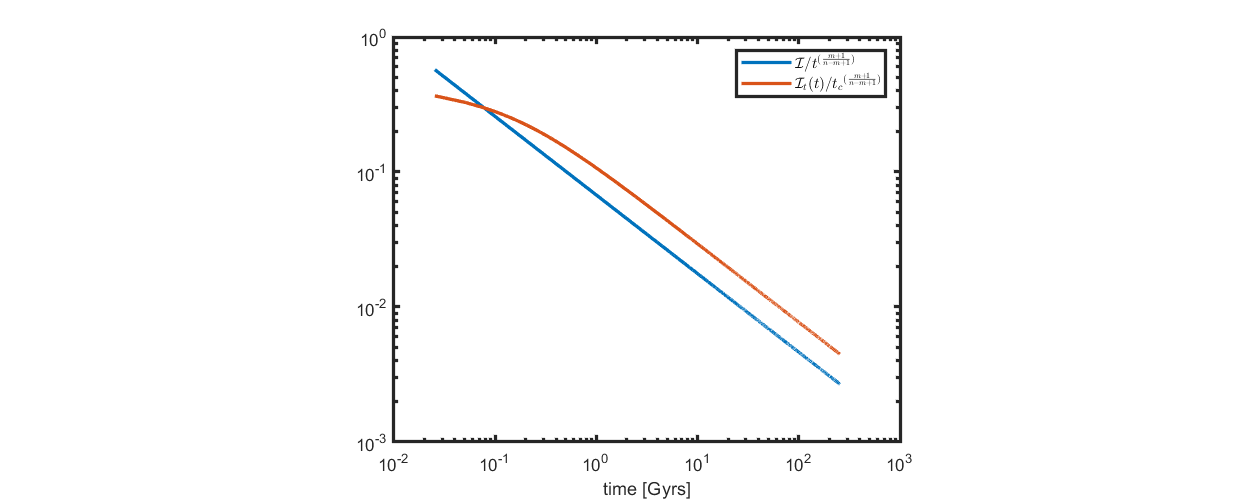

figure('position',[10 10 1000 400])

%M_num_dimensional = 2*rho*phi0_best(phi_s,m_exp)*pi*R_mars^2*(R_mars/D_hyd(phi_s,m_exp,n_exp))^((m_exp+1)/(n_exp-m_exp+1)).*M;

%loglog(time_vec*tc_here/yr2s/1e9,*M_num_dimensional), hold on
%loglog(time_vec*tc_here/yr2s/1e9,Int.*M_theory(time_vec*tc_here)); hold on
%loglog(time_vec*tc_here/yr2s/1e9,(M.*(m_exp+1))./tc_here^((m_exp+1)/(n_exp-m_exp+1)));

loglog(time_vec*tc_here/yr2s/1e9,Int*M_theory(time_vec)); hold on
loglog(time_vec*tc_here/yr2s/1e9,(M.*(m_exp+1)));


pbaspect([1 .8 1])
xlim([1e-2,1e3])
%ylim([1e-3 1e0])
legend('$\mathcal{I}/t^{(\frac{m+1}{n-m+1})}$','$\mathcal{I}_t(t)/{t_c}^{(\frac{m+1}{n-m+1})}$','Interpreter','latex')
ylabel ''
xlabel 'time [Gyrs]'

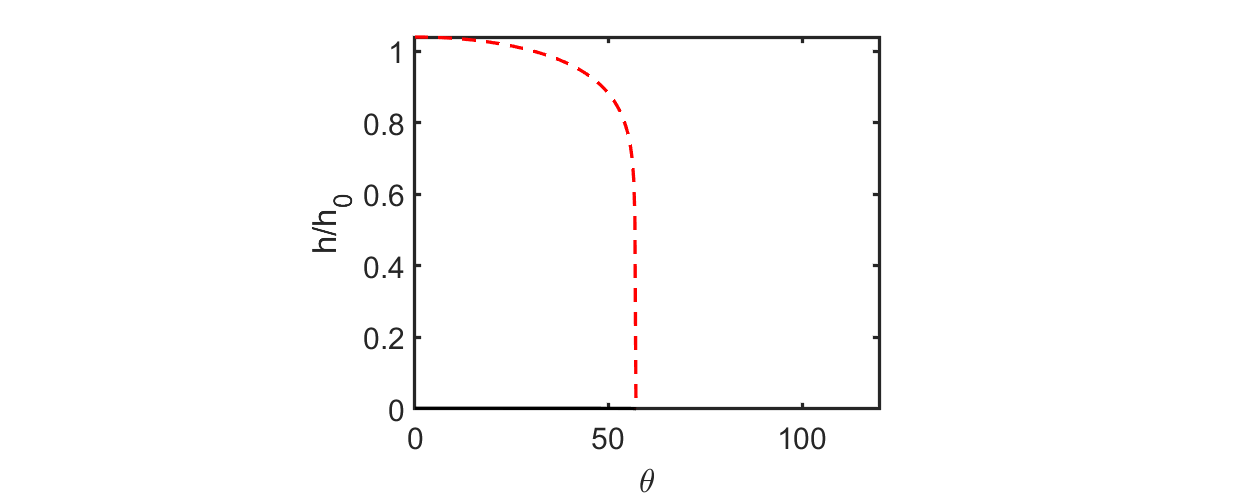


figure('position',[10 10 1000 400])
plot(rad2deg(Grid.xc),hD*h0/h_c,'k-'), hold on  %.*M_theory(time_vec(end))
plot(rad2deg(Grid.xc),u,'r--')
xlabel '\theta', ylabel 'h/h_0'
xlim([0 120])
%ylim([0 1])
pbaspect([1 .8 1])

## Auxillary functions

#### solve_self_similar_ode

function [u] = solve_self_similar_ode(res,u,n,m,B,N,BC,kmax)
eps_jac = 1e-6;     % perturbation for numerical Jacobian
tol = 1e-6;         % convergence tolerance

nres = norm(res(u,n,m)); ndu = 1; k = 0;
while (nres > tol || ndu > tol) && k < kmax
    Jac_num = comp_jacobian_selfsimilar(res,u,eps_jac,n,m);
    du = solve_lbvp(Jac_num,-res(u,n,m),B,BC.g,N); 
    u = u + du;
    nres = norm(N'*res(u,n,m)); ndu = norm(N'*du);
    k = k+1;
    fprintf('it = %d: nres = %3.2e  ndu = %3.2e\n',k,nres,ndu)
    if k == 1; ndu = 0; end % to allow exit on first iteration
end
if k == kmax; fprintf('Newton-Raphson did not converge in %d iterations.\n',k); end
end

#### plot_self_similar_soln

function [] = plot_self_similar_soln(Grid,u,n,m)


z = linspace(0,1,1e2);
% subplot('Position',[ode_x ode_y subW_ode/figW subH_ode/figH])
plot(Grid.xc,u,'-'), hold on
xlabel 'x/L'
ylabel 'f'
pbaspect([1 .5 1])


end


#### comp_jacobian_selfsimilar

function [J] = comp_jacobian_selfsimilar(r,u,eps,n,m)
N=length(u);
u_perturb=u;
for i=1:N
   u_perturb(i)=u_perturb(i)+eps;
   J(:,i)=(r(u_perturb,n,m)-r(u,n,m))/eps;
   u_perturb(i)=u(i);
end
end

#### plot_mvsIntegral

function [] = plot_Integralvsm(m_vec,Int)

figure()
plot(m_vec,Int','-'), hold on
xlabel('$m$','Interpreter','latex')
ylabel('$\mathcal{I}$','Interpreter','latex')

pbaspect([1 .5 1])

end
